# von Karman beam with 1:3 internal resonance

In this example, we consider a clamped-pinned von Karman beam with a support spring at its midspan. The stiffness of the support spring is tund such that 1:3 internal resonance occurs between the first two bending modes. We then extract the forced response curve using SSM reduction. 

clear all

## Model Setup

Building FE model


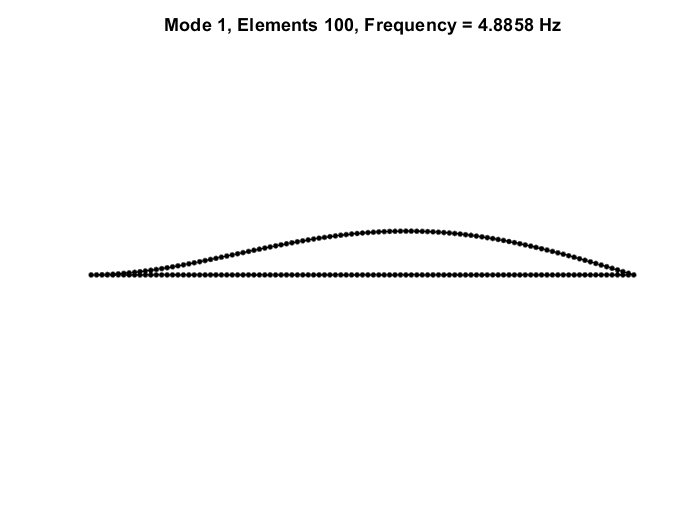

Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem
Getting nonlinearity coefficients
Assembling Tensors
Assembling external force vector


nElements = 100;
[M,~,K,fnl,~,Outdof] = build_model(nElements);

outdof = Outdof(2); % the point at mid span
n = length(M);
Kc = K;

The beam is discretized with 100 elements and then 298 degrees-of-freedom. The dimension of phase space of the full system is 596. With the SSM reduction, the dimension of phase space will be reduced to four. Numerical experiments show that 1:3 near resonance is observed when the stiffness of the support spring is around 37. Next we set the stiffness to be 37 and then perform SSM reduction.

## Dynamical System Setup

kLinear = 37;
Kc(outdof,outdof) = K(outdof,outdof)+kLinear;   % linear part
kNonlinear = 0;                                 % nonlinear part
f3_new  = fnl{2};
fnl_new = fnl;
f3_new(outdof,outdof,outdof,outdof) = f3_new(outdof,outdof,outdof,outdof)+kNonlinear; % cubic nonlinerity
fnl_new{2} = f3_new;
C = (2e-4)/9*Kc;

DSorder = 2;
DS = DynamicalSystem(DSorder);
set(DS,'M',M,'C',C,'K',Kc,'fnl',fnl_new);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex');

## Primiary resonance with IRs

**Add forcing -  a concentric harmonic force is applied at the midspan**

f_0 = zeros(n,1);
f_0(outdof) = 1000;
kappas = [-1; 1];
epsilon   = 0.02;
coeffs = epsilon * [f_0 f_0]/2;
DS.add_forcing(coeffs, kappas);

**Create SSM**

S = SSM(DS);
set(S.Options, 'reltol', 0.8,'notation','multiindex')

**Extract FRC**

Here we use the extract_FRC routine to obtain the forced response curve over $[0.96,1.05]\omega_1$.

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 3.688485e-04
modal damping ratio for 2 mode is 1.106767e-03
modal damping ratio for 3 mode is 2.309722e-03
modal damping ratio for 4 mode is 3.944138e-03
modal damping ratio for 5 mode is 6.019377e-03

 The first 10 eigenvalues are given as 
   1.0e+02 *

  -0.0001 + 0.3320i
  -0.0001 - 0.3320i
  -0.0011 + 0.9961i
  -0.0011 - 0.9961i
  -0.0048 + 2.0787i
  -0.0048 - 2.0787i
  -0.0140 + 3.5497i
  -0.0140 - 3.5497i
  -0.0326 + 5.4173i
  -0.0326 - 5.4173i

The master subspace has internal resonances: [1  1  3  3]
*****************************************
Calculating FRC using SSM with master subspace: [1  2  3  4]
(near) outer resonance detected for the following combination of master eigenvalues
     0     0     2     0
     1     0     

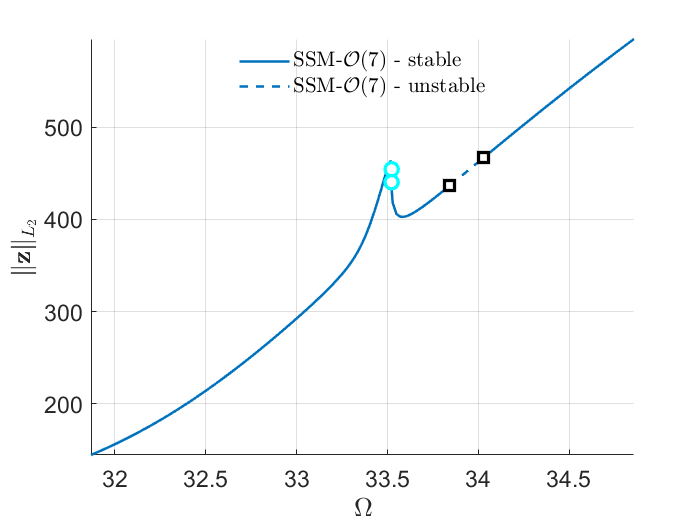

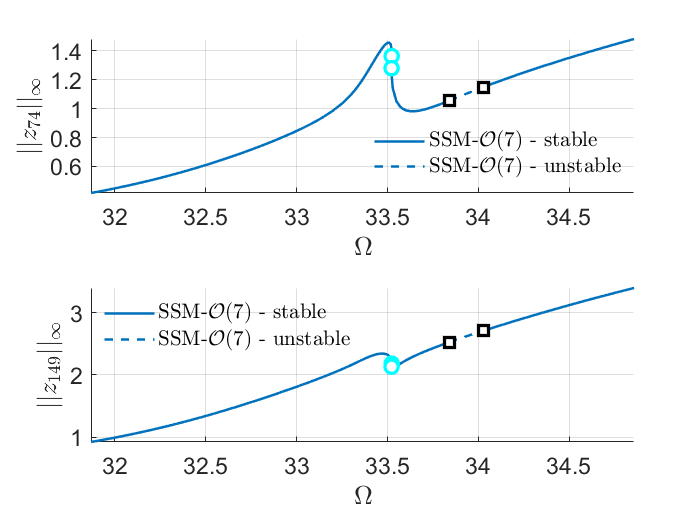

Total time spent on FRC computation upto O(7) = 00:00:39


om = eigs(Kc,M,2,'smallestabs');
om = sqrt(om);
freqRange = [0.96 1.05]*om(1);
order = 7;
set(S.FRCOptions, 'nCycle',50000);
set(S.FRCOptions, 'initialSolver','forward');
set(S.contOptions, 'h_max', 0.2, 'PtMX', 1000, 'ItMX',20);
set(S.FRCOptions, 'omegaSampStyle','cocoBD');
set(S.FRCOptions, 'method','continuation ep','outdof',Outdof');
FRC = S.extract_FRC('freq', freqRange, order);

As an alternative, we can use SSM-ep toolbox to obtain the curve. We also change coordinate representation to Cartesian. The two coordinates yield the same results.

(near) outer resonance detected for the following combination of master eigenvalues
     0     0     2     0
     1     0     2     0
     0     0     3     1
     1     1     2     0
     3     0     1     0
     0     2     3     0
     1     0     3     1
     2     1     2     0
     4     0     1     0
     0     0     4     2
     0     3     3     0
     1     1     3     1
     2     2     2     0
     3     0     2     1
     4     1     1     0
     6     0     0     0
     0     2     4     1
     1     0     4     2
     1     3     3     0
     2     1     3     1
     3     2     2     0
     4     0     2     1
     5     1     1     0
     7     0     0     0
     0     0     5     3
     0     3     4     1
     1     1     4     2
     1     4     3     0
     2     2     3     1
     3     0     3     2
     3     3     2     0
     4     1     2     1
     5     2     1     0
     6     0     1     1
     7     1     0     0
     0     2     5     2
     0     5    

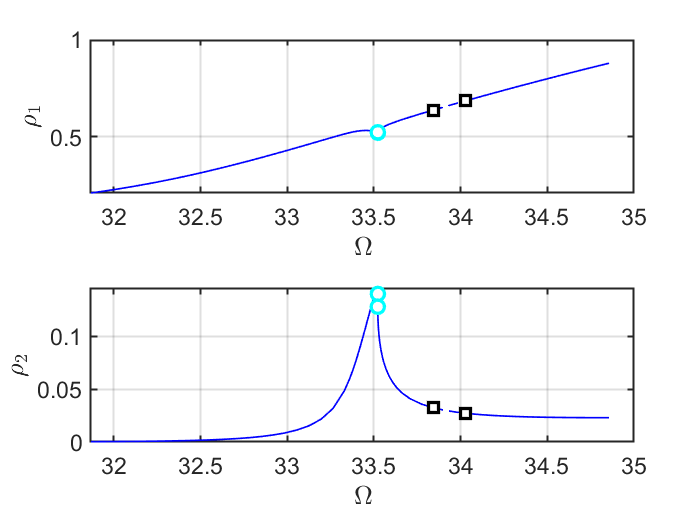

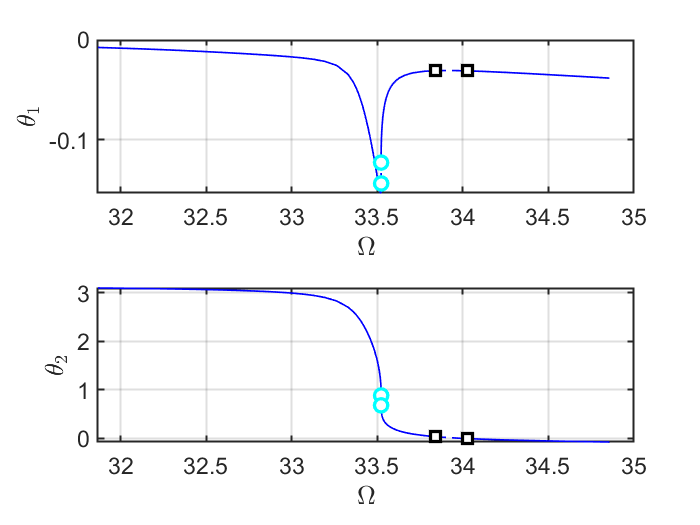

the forcing frequency 3.1869e+01 is nearly resonant with the eigenvalue -1.2244e-02 + i3.3196e+01
the forcing frequency 3.1881e+01 is nearly resonant with the eigenvalue -1.2244e-02 + i3.3196e+01
the forcing frequency 3.1951e+01 is nearly resonant with the eigenvalue -1.2244e-02 + i3.3196e+01
the forcing frequency 3.2021e+01 is nearly resonant with the eigenvalue -1.2244e-02 + i3.3196e+01
the forcing frequency 3.2091e+01 is nearly resonant with the eigenvalue -1.2244e-02 + i3.3196e+01
the forcing frequency 3.2161e+01 is nearly resonant with the eigenvalue -1.2244e-02 + i3.3196e+01
the forcing frequency 3.2231e+01 is nearly resonant with the eigenvalue -1.2244e-02 + i3.3196e+01
the forcing frequency 3.2301e+01 is nearly resonant with the eigenvalue -1.2244e-02 + i3.3196e+01
the forcing frequency 3.2370e+01 is nearly resonant with the eigenvalue -1.2244e-02 + i3.3196e+01
the forcing frequency 3.2440e+01 is nearly resonant with the eigenvalue -1.2244e-02 + i3.3196e+01
the forcing frequenc

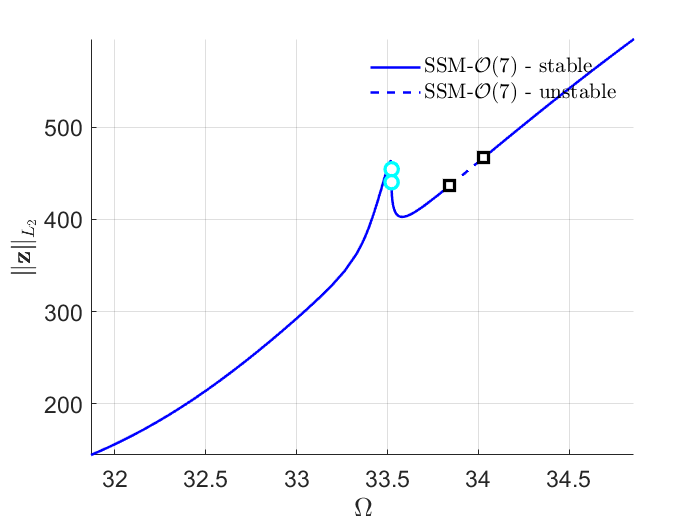

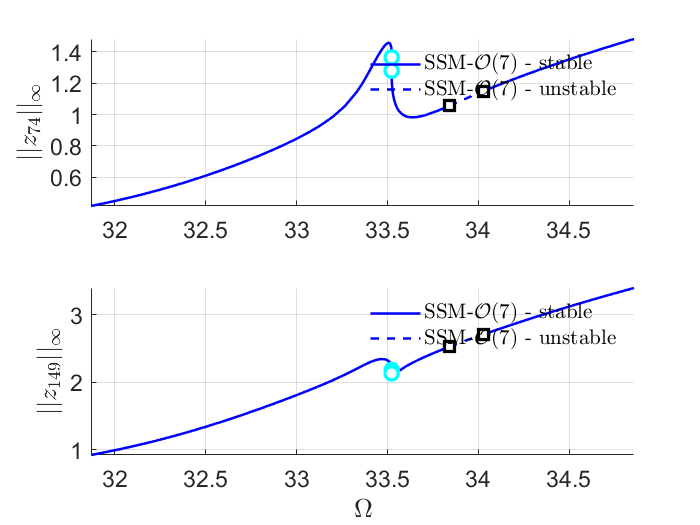

set(S.FRCOptions, 'coordinates', 'cartesian');
set(S.contOptions, 'h_min',1e-2,'h_max',0.1); 
S.SSM_isol2ep('isol',[1 2 3 4],order,[1 3],'freq',freqRange,Outdof);

**Quasi-periodic response**

In the above continuation run of fixed points, two Hopf bifurcation points were observed. We switch the continuation of fixed points to the continuation of periodic orbits that are born out of the bifurcation points. Specifically, we use SSM-po toolbox to do that.


 Run='po.po': Continue periodic orbits born from HB point.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          6.62e-06  4.88e+01    0.0    0.0    0.0
   1   1  1.00e+00  3.72e-06  3.17e-12  4.88e+01    0.0    0.0    0.0
   2   1  1.00e+00  1.14e-10  4.41e-15  4.88e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om    po.period          eps
    0  00:00:00   4.8786e+01      1  EP      3.3841e+01   5.8471e+00   1.0000e+00
    2  00:00:00   4.8787e+01      2          3.3842e+01   5.8459e+00   1.0000e+00
    4  00:00:01   4.8772e+01      3          3.3845e+01   5.8407e+00   1.0000e+00
    6  00:00:01   4.8781e+01      4          3.3851e+01   5.8346e+00   1.0000e+00
    8  00:00:01   4.8795e+01      5          3.3860e+01   5.8326e+00   1.0000e+00
   10  00:00:01   4.8854e+01      6          3.3868e+01   5.8398e+00   1.0000e+00
   12  00:00:0

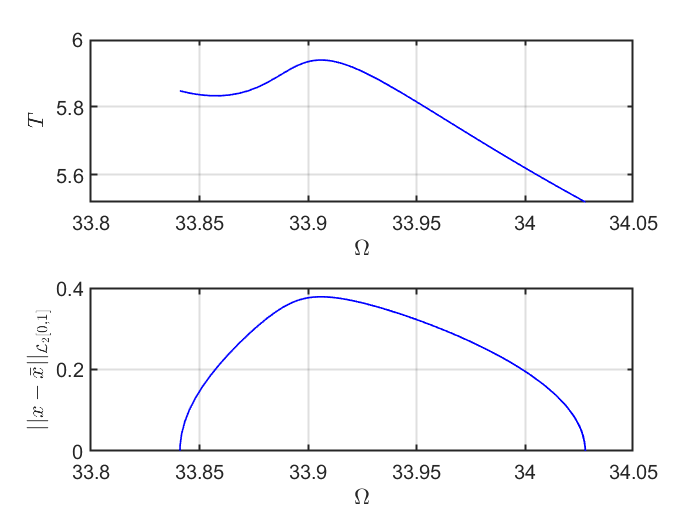

Constructing torus in reduced dynamical system
Interpolation at frequency 3.384095e+01
Interpolation at frequency 3.384171e+01
Interpolation at frequency 3.384522e+01
Interpolation at frequency 3.385132e+01
Interpolation at frequency 3.385951e+01
Interpolation at frequency 3.386819e+01
Interpolation at frequency 3.387664e+01
Interpolation at frequency 3.388535e+01
Interpolation at frequency 3.389181e+01
Interpolation at frequency 3.389603e+01
Interpolation at frequency 3.389888e+01
Interpolation at frequency 3.390102e+01
Interpolation at frequency 3.390279e+01
Interpolation at frequency 3.390437e+01
Interpolation at frequency 3.390586e+01
Interpolation at frequency 3.390739e+01
Interpolation at frequency 3.390894e+01
Interpolation at frequency 3.391060e+01
Interpolation at frequency 3.391247e+01
Interpolation at frequency 3.391467e+01
Interpolation at frequency 3.391738e+01
Interpolation at frequency 3.392086e+01
Interpolation at frequency 3.392558e+01
Interpolation at frequency 3.3932

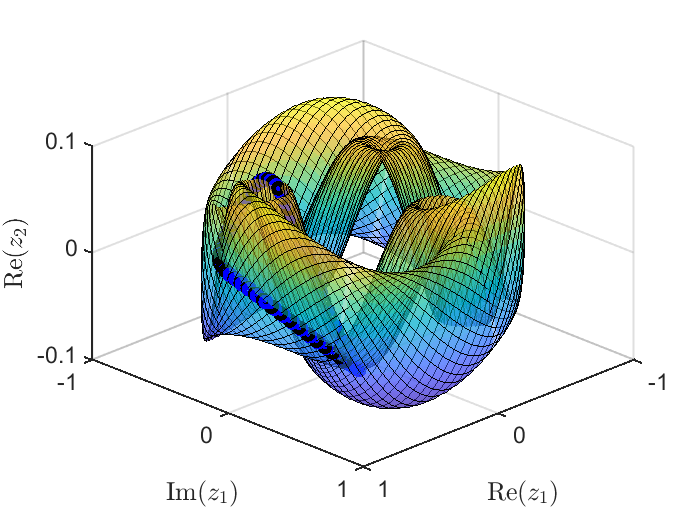

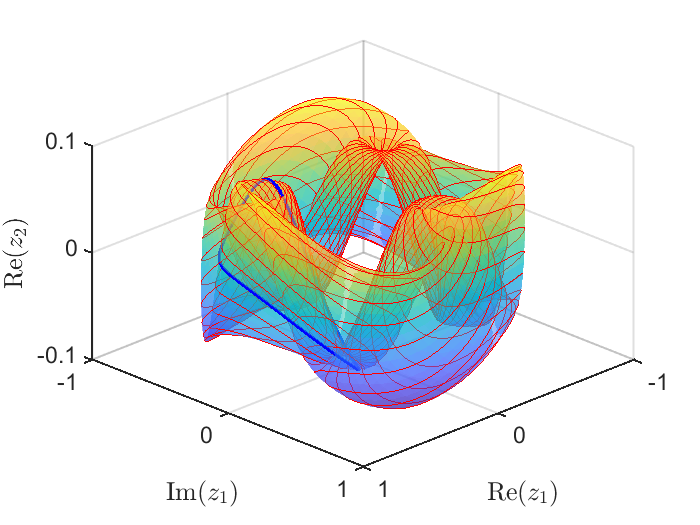


 FRCs from ='po.po': generating torus in physical domain.


HBlab = 15;
set(S.contOptions, 'h_max',0.2,'PtMX',90,'NAdapt',2, 'bi_direct', false,'NSV',2);              % continuation setting
S.SSM_HB2po('po','isol',HBlab,'freq',freqRange,[Outdof; Outdof+n],'saveICs');

**Plot of FRC for quasi-periodic orbits**

% calculate the amplitude of qausi-periodic orbits
runid = 'po';
samps = 1:2:33;
bd   = coco_bd_read([runid,'.po']);
lab  = coco_bd_labs(bd, 'FP');
labs = [1:lab-1 lab+1];
lab  = numel(labs);
x1_tr = zeros(lab,1);
x2_tr = zeros(lab,1);
om_tr = zeros(lab,1);
st    = false(lab,1);
for i=1:lab
    sol = SSM_po_read_solution(runid,labs(i));
    st(i)    = sol.st;
    om_tr(i) = sol.om;
    x1i      = sol.xTr(:,1,:);
    x2i      = sol.xTr(:,2,:);
    x1_tr(i) = norm(x1i(:),'inf');
    x2_tr(i) = norm(x2i(:),'inf');
end

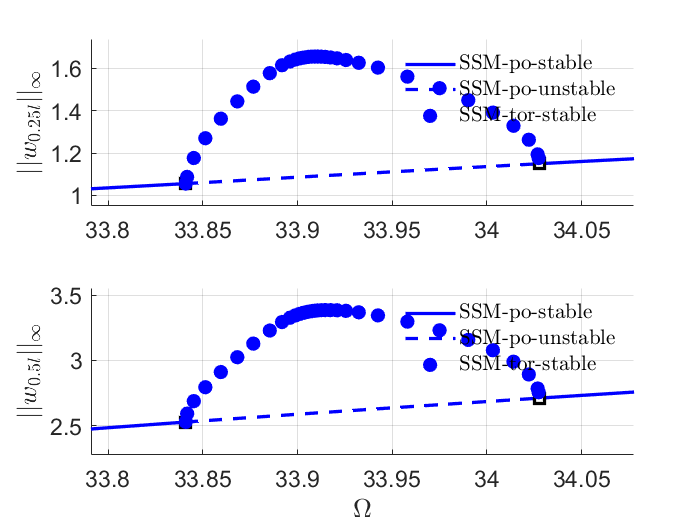

% background periodic response
SSMRes = load('data\isol.ep\SSMep.mat');
FRC = SSMRes.FRC;
% plot results of periodic reponse and tori in the same figure
ST = cell(2,1);
ST{1} = {'b--','LineWidth',2}; % unstable
ST{2} = {'b-','LineWidth',2};  % stable
legs = 'SSM-po-unstable';
legu = 'SSM-po-stable';
thm = struct();
thm.SN = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'cyan', 'Marker', 'o', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'cyan', 'MarkerFaceColor', 'white'};
thm.HB = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'black', 'Marker', 's', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'black', 'MarkerFaceColor', 'white'};

SNidx = FRC.SNidx;
HBidx = FRC.HBidx;
FRC.st = double(FRC.st);
FRC.st(HBidx) = nan;
FRC.st(SNidx) = nan;
figure;
subplot(2,1,1); hold on
plot_stab_lines(FRC.om,FRC.Aout_frc(:,1),FRC.st,ST,legs,legu);
SNfig = plot(FRC.om(SNidx),FRC.Aout_frc(SNidx,1),thm.SN{:});
set(get(get(SNfig,'Annotation'),'LegendInformation'),...
'IconDisplayStyle','off');
HBfig = plot(FRC.om(HBidx),FRC.Aout_frc(HBidx,1),thm.HB{:});
set(get(get(HBfig,'Annotation'),'LegendInformation'),...
'IconDisplayStyle','off');   
ylabel('$||w_{0.25l}||_{\infty}$','Interpreter','latex'); 
set(gca,'FontSize',14);
grid on, axis tight; 
legend boxoff;
subplot(2,1,2); hold on
plot_stab_lines(FRC.om,FRC.Aout_frc(:,2),FRC.st,ST,legs,legu);
SNfig = plot(FRC.om(SNidx),FRC.Aout_frc(SNidx,2),thm.SN{:});
set(get(get(SNfig,'Annotation'),'LegendInformation'),...
'IconDisplayStyle','off');
HBfig = plot(FRC.om(HBidx),FRC.Aout_frc(HBidx,2),thm.HB{:});
set(get(get(HBfig,'Annotation'),'LegendInformation'),...
'IconDisplayStyle','off');   
xlabel('$\Omega$','Interpreter','latex'); 
ylabel('$||w_{0.5l}||_{\infty}$','Interpreter','latex'); 
grid on;

figure(gcf); 
subplot(2,1,1);
plot(om_tr(st), x1_tr(st), 'o','MarkerSize', 8, 'MarkerEdgeColor', ...
  'blue', 'MarkerFaceColor', 'blue','DisplayName','SSM-tor-stable');
plot(om_tr(~st), x1_tr(~st), 'o','MarkerSize', 8, 'MarkerEdgeColor', ...
  'red', 'MarkerFaceColor', 'red','DisplayName','SSM-tor-unstable');
lowb = 0.9*min(FRC.Aout_frc(HBidx,1));
upb  = 1.05*max(x1_tr);
axis([min(FRC.om(HBidx))-0.05,max(FRC.om(HBidx))+0.05,lowb,upb]);
subplot(2,1,2);
plot(om_tr(st), x2_tr(st), 'o','MarkerSize', 8, 'MarkerEdgeColor', ...
  'blue', 'MarkerFaceColor', 'blue','DisplayName','SSM-tor-stable');
plot(om_tr(~st), x2_tr(~st), 'o','MarkerSize', 8, 'MarkerEdgeColor', ...
  'red', 'MarkerFaceColor', 'red','DisplayName','SSM-tor-unstable');
lowb = 0.9*min(FRC.Aout_frc(HBidx,2));
upb  = 1.05*max(x2_tr);
axis([min(FRC.om(HBidx))-0.05,max(FRC.om(HBidx))+0.05,lowb,upb]);
set(gca,'FontSize',14);
legend boxoff;

**Exercises**

- Use SSM_isol2ep to calculate the forced response curve with varied forcing amplitude $\epsilon$.

- Use SSM_ep2SN to locate the solution manifold of saddle-node bifurcation periodic orbits.

- Use SSM_ep2HB to locate the solution manifold of torus bifurcation periodic orbits.

- Use SSM_HB2po to extract FRC for quasi-periodic orbits from the other HB point in 'isol' run.

- Use SSM_HB2po to extract FRC for quasi-periodic orbits with varied forcing amplitude $\epsilon$.

- Use SSM_po2po to extract FRC for quasi-periodic orbits with varied forcing frequency $\Omega$ or amplitude $\epsilon$.